% MATLAB Code for Step Response and Performance Data Analysis
% -----------------------------------------------------------
% This script analyzes the transient response and steady-state characteristics
% of the uncompensated closed-loop system.
% This version is corrected to be compatible with all MATLAB versions.

% Clear workspace, command window, and close all figures for a clean run
clear;
clc;
close all;

% --- 1. Define the System ---
% We need the CLOSED-LOOP transfer function (T_s) for step response analysis.
num_ol = [-10.07];       % Open-loop numerator
den_ol = [1, 1806, 4843]; % Open-loop denominator
G_ol = tf(num_ol, den_ol);

% Create the closed-loop system using the feedback command.
T_s = feedback(G_ol, 1);

% Display the closed-loop transfer function to verify.
disp('Closed-Loop Transfer Function (T_s):');

Closed-Loop Transfer Function (T_s):


T_s


T_s =
 
        -10.07
  -------------------
  s^2 + 1806 s + 4833
 
Continuous-time transfer function.
Model Properties


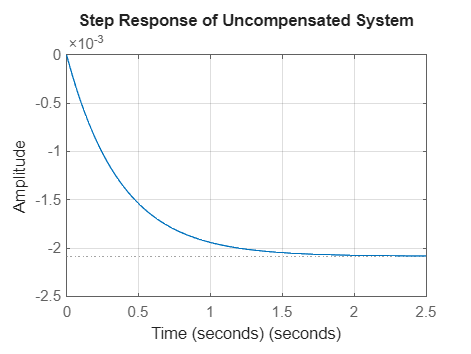


% --- 2. Generate and Display the Step Response Plot ---
% Create a new figure window for the plot.
figure;

% Generate the step response plot for the closed-loop system.
step(T_s);

% Enhance the plot for your report.
title('Step Response of Uncompensated System');
xlabel('Time (seconds)');
ylabel('Amplitude');
grid on;


% --- 3. Automatically Calculate and Display Performance Data ---
% Use the 'stepinfo' function to extract all key metrics.
info = stepinfo(T_s);

% Display the calculated data in a clear format in the command window.
fprintf('\n--- System Performance Data ---\n');


--- System Performance Data ---


fprintf('Rise Time: %.4f seconds\n', info.RiseTime);

Rise Time: 0.8198 seconds


fprintf('Settling Time (2%% criterion): %.4f seconds\n', info.SettlingTime);

Settling Time (2% criterion): 1.4603 seconds


fprintf('Overshoot: %.2f%%\n', info.Overshoot);

Overshoot: 0.00%


fprintf('Peak Value: %.4f\n', info.Peak);

Peak Value: 0.0021



% --- 4. Calculate Final Value and Steady-State Error (Corrected Method) ---
% For a system with 0% overshoot, the 'Peak' value is the same as the
% final steady-state value. This method avoids the "SteadyStateValue"
% field error found in some MATLAB versions.
final_value = info.Peak;
fprintf('Final Steady-State Value: %.4f\n', final_value);

Final Steady-State Value: 0.0021



% Calculate the error based on a unit step input (reference = 1).
steady_state_error = 1 - final_value;
fprintf('Steady-State Error (ess): %.4f\n', steady_state_error);

Steady-State Error (ess): 0.9979


fprintf('-----------------------------\n');

-----------------------------
